Bild: Geschwindigkeitsempfehlung_30-2025-06-19__20.jpg


Blau Roh                         | Blobs:    0 | Pixel:      0 | BBox:     0 x     0 =       0


Blau Close                       | Blobs:    0 | Pixel:      0 | BBox:     0 x     0 =       0


Blau Fill                        | Blobs:    0 | Pixel:      0 | BBox:     0 x     0 =       0


Dunkelblau Roh                   | Blobs:   17 | Pixel:    105 | BBox:    12 x    24 =     288


Dunkelblau Close                 | Blobs:   14 | Pixel:    152 | BBox:    34 x    14 =     476


Dunkelblau Fill                  | Blobs:   14 | Pixel:    152 | BBox:    34 x    14 =     476


Blau ODER Dunkelblau nach Fill   | Blobs:   14 | Pixel:    152 | BBox:    34 x    14 =     476



Beliebige Taste im Analysefenster = nächstes Bild


Bild: Geschwindigkeitsempfehlung_30-2025-06-19__34.jpg


Blau Roh                         | Blobs:    5 | Pixel:     40 | BBox:    23 x     4 =      92


Blau Close                       | Blobs:    4 | Pixel:     42 | BBox:    23 x     4 =      92


Blau Fill                        | Blobs:    4 | Pixel:     42 | BBox:    23 x     4 =      92


Dunkelblau Roh                   | Blobs:   17 | Pixel:    178 | BBox:    15 x    21 =     315


Dunkelblau Close                 | Blobs:    9 | Pixel:    444 | BBox:    19 x    42 =     798


Dunkelblau Fill                  | Blobs:    9 | Pixel:    444 | BBox:    19 x    42 =     798


Blau ODER Dunkelblau nach Fill   | Blobs:   12 | Pixel:    486 | BBox:    31 x    42 =    1302



Beliebige Taste im Analysefenster = nächstes Bild


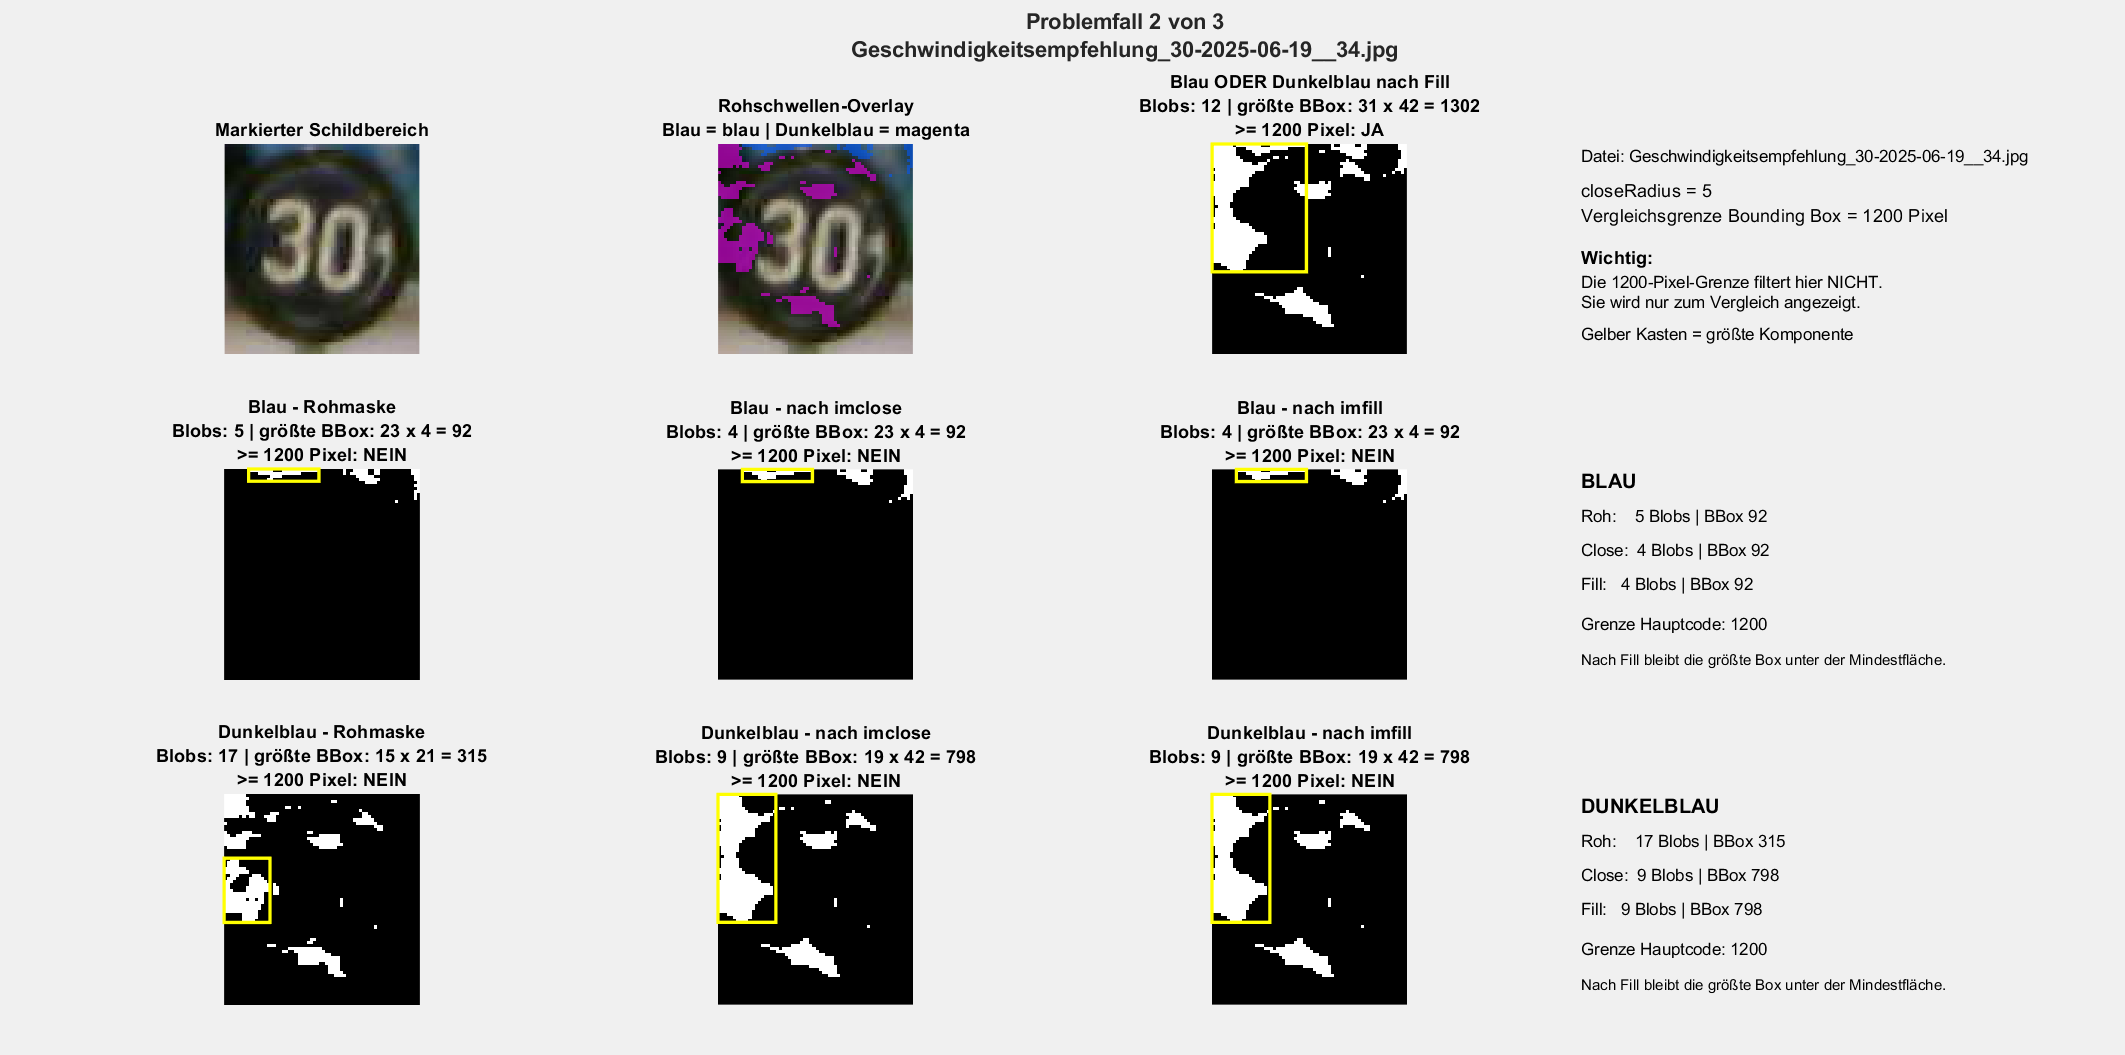

%% =========================================================
% Gezielte Analyse kleiner blauer/dunkelblauer Schilder
%
% Ziel:
%   Für einzelne Problem-Bilder wird das Schild manuell als ROI markiert.
%   Danach wird NUR untersucht, was mit den bestehenden Farbschwellen
%   und der bestehenden Maskennachverarbeitung passiert:
%
%       Rohmaske -> imclose -> imfill -> zusammenhängende Komponenten
%
% Es werden KEINE neuen Farbschwellen und KEINE neuen Filter eingeführt.
%
% Bestehende Werte aus dem aktuellen Hauptcode:
%   Blau:
%       L 15..55, a -5..8, b -27..-14
%   Dunkelblau:
%       L 2..14, a -8..3, b -9..4
%   closeRadius = 5
%   minBoundingBoxArea = 1200
%
% Die Mindestfläche wird hier NICHT zum Entfernen verwendet.
% Sie wird nur angezeigt, damit sichtbar wird, ob ein gefundener Blob
% im Hauptcode an der 1200-Pixel-Grenze scheitern würde.
% ==========================================================

clear;
clc;
close all;

%% 1. Bestehende Parameter

blueThreshold = [ ...
    15, 55, ...
    -5, 8, ...
    -27, -14];

darkBlueThreshold = [ ...
    2, 14, ...
    -8, 3, ...
    -9, 4];

closeRadius = 5;

% Nur zum Vergleich mit dem aktuellen Hauptcode.
% Dieser Wert filtert in diesem Testskript NICHTS heraus.
minBoundingBoxArea = 1200;


%% 2. Bilder auswählen

startFolder = ...
    "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";

[fileNames, folderName] = uigetfile( ...
    { ...
        '*.jpg;*.jpeg;*.png;*.bmp;*.tif;*.tiff', ...
        'Bilddateien' ...
    }, ...
    'Problem-Bilder auswählen', ...
    char(startFolder), ...
    'MultiSelect', ...
    'on');

if isequal(fileNames, 0)
    error('Es wurden keine Bilder ausgewählt.');
end

if ischar(fileNames)
    fileNames = {fileNames};
end


%% 3. Ergebnistabelle vorbereiten

results = table( ...
    cell(0,1), ...      % Bildname
    cell(0,1), ...      % Schwelle
    cell(0,1), ...      % Verarbeitungsschritt
    zeros(0,1), ...     % Anzahl Blobs
    zeros(0,1), ...     % größte Pixel-Fläche
    zeros(0,1), ...     % BoundingBox Breite
    zeros(0,1), ...     % BoundingBox Höhe
    zeros(0,1), ...     % BoundingBox Fläche
    cell(0,1), ...      % >= 1200?
    'VariableNames', ...
    { ...
        'Bildname', ...
        'Schwelle', ...
        'Stufe', ...
        'AnzahlBlobs', ...
        'GroessteBlobPixelflaeche', ...
        'GroessteBoundingBoxBreite', ...
        'GroessteBoundingBoxHoehe', ...
        'GroessteBoundingBoxFlaeche', ...
        'BestehtMinBoundingBoxArea' ...
    });


%% 4. Bilder einzeln untersuchen

for imageNumber = 1:numel(fileNames)

    imagePath = fullfile( ...
        folderName, ...
        fileNames{imageNumber});

    I = imread(imagePath);

    if ndims(I) == 2 || size(I,3) == 1
        I = repmat(I, 1, 1, 3);
    end

    if size(I,3) > 3
        I = I(:,:,1:3);
    end


    %% 4a. Schild manuell markieren

    selectionFigure = figure( ...
        'Name', ...
        sprintf( ...
            'ROI markieren | Bild %d von %d', ...
            imageNumber, ...
            numel(fileNames)), ...
        'NumberTitle', ...
        'off', ...
        'Position', ...
        [100, 100, 1200, 750]);

    imshow(I);

    title( ...
        { ...
            fileNames{imageNumber}; ...
            'Rechteck möglichst eng um das Schild ziehen'; ...
            'Doppelklick in das Rechteck = übernehmen' ...
        }, ...
        'Interpreter', ...
        'none');

    roiObject = drawrectangle( ...
        'Color', ...
        'y');

    wait(roiObject);

    roiPosition = roiObject.Position;

    if ishandle(selectionFigure)
        close(selectionFigure);
    end


    %% 4b. ROI ausschneiden

    x1 = max(1, floor(roiPosition(1)));
    y1 = max(1, floor(roiPosition(2)));

    x2 = min( ...
        size(I,2), ...
        ceil(roiPosition(1) + roiPosition(3)));

    y2 = min( ...
        size(I,1), ...
        ceil(roiPosition(2) + roiPosition(4)));

    roiImage = I(y1:y2, x1:x2, :);


    %% 4c. ROI nach LAB umwandeln

    labImage = rgb2lab(roiImage);

    L = labImage(:,:,1);
    A = labImage(:,:,2);
    B = labImage(:,:,3);


    %% 4d. Reine Farbschwellen

    blueRaw = createLabMask( ...
        L, A, B, ...
        blueThreshold);

    darkBlueRaw = createLabMask( ...
        L, A, B, ...
        darkBlueThreshold);


    %% 4e. Bestehendes morphologisches Schließen

    structuralElement = strel( ...
        'disk', ...
        closeRadius, ...
        0);

    blueClosed = imclose( ...
        blueRaw, ...
        structuralElement);

    darkBlueClosed = imclose( ...
        darkBlueRaw, ...
        structuralElement);


    %% 4f. Bestehendes Auffüllen

    blueFilled = imfill( ...
        blueClosed, ...
        'holes');

    darkBlueFilled = imfill( ...
        darkBlueClosed, ...
        'holes');


    %% 4g. Nur zur Diagnose:
    %      Kombination der fertigen Blau-/Dunkelblau-Masken.
    %      Diese Kombination wird NICHT als neuer Filter verwendet.

    combinedFilled = ...
        blueFilled | darkBlueFilled;


    %% 4h. Kennzahlen bestimmen

    blueRawInfo = analyzeComponents( ...
        blueRaw, ...
        minBoundingBoxArea);

    blueClosedInfo = analyzeComponents( ...
        blueClosed, ...
        minBoundingBoxArea);

    blueFilledInfo = analyzeComponents( ...
        blueFilled, ...
        minBoundingBoxArea);


    darkRawInfo = analyzeComponents( ...
        darkBlueRaw, ...
        minBoundingBoxArea);

    darkClosedInfo = analyzeComponents( ...
        darkBlueClosed, ...
        minBoundingBoxArea);

    darkFilledInfo = analyzeComponents( ...
        darkBlueFilled, ...
        minBoundingBoxArea);


    combinedInfo = analyzeComponents( ...
        combinedFilled, ...
        minBoundingBoxArea);


    %% 4i. Werte in Tabelle eintragen

    imageName = fileNames{imageNumber};

    results = [
        results;
        makeResultRow(imageName, 'Blau',       'Rohmaske',  blueRawInfo);
        makeResultRow(imageName, 'Blau',       'NachClose', blueClosedInfo);
        makeResultRow(imageName, 'Blau',       'NachFill',  blueFilledInfo);
        makeResultRow(imageName, 'Dunkelblau', 'Rohmaske',  darkRawInfo);
        makeResultRow(imageName, 'Dunkelblau', 'NachClose', darkClosedInfo);
        makeResultRow(imageName, 'Dunkelblau', 'NachFill',  darkFilledInfo);
        makeResultRow(imageName, 'BlauODERDunkelblau', ...
            'NachFill', combinedInfo)
    ];


    %% 4j. Detailansicht

    fig = figure( ...
        'Name', ...
        sprintf( ...
            'Detailanalyse | %s', ...
            imageName), ...
        'NumberTitle', ...
        'off', ...
        'Position', ...
        [40, 40, 1700, 900]);

    tiledlayout( ...
        3, ...
        4, ...
        'TileSpacing', ...
        'compact', ...
        'Padding', ...
        'compact');


    % ---------------------------------------------------------
    % Zeile 1: Original / Overlay / Information
    % ---------------------------------------------------------

    nexttile;
    imshow(roiImage);
    title( ...
        'Markierter Schildbereich', ...
        'Interpreter', ...
        'none');


    nexttile;
    overlayImage = createOverlay( ...
        roiImage, ...
        blueRaw, ...
        darkBlueRaw);

    imshow(overlayImage);

    title( ...
        { ...
            'Rohschwellen-Overlay'; ...
            'Blau = blau | Dunkelblau = magenta' ...
        });


    nexttile;
    imshow(combinedFilled);
    hold on;

    drawLargestBoundingBox( ...
        combinedInfo, ...
        'y');

    hold off;

    title( ...
        createInfoTitle( ...
            'Blau ODER Dunkelblau nach Fill', ...
            combinedInfo, ...
            minBoundingBoxArea));


    nexttile;
    axis off;

    text( ...
        0, 0.95, ...
        sprintf('Datei: %s', imageName), ...
        'Interpreter', ...
        'none', ...
        'FontSize', ...
        10);

    text( ...
        0, 0.78, ...
        sprintf('closeRadius = %d', closeRadius), ...
        'FontSize', ...
        11);

    text( ...
        0, 0.66, ...
        sprintf( ...
            'Vergleichsgrenze Bounding Box = %d Pixel', ...
            minBoundingBoxArea), ...
        'FontSize', ...
        11);

    text( ...
        0, 0.46, ...
        'Wichtig:', ...
        'FontWeight', ...
        'bold', ...
        'FontSize', ...
        11);

    text( ...
        0, 0.35, ...
        'Die 1200-Pixel-Grenze filtert hier NICHT.', ...
        'FontSize', ...
        10);

    text( ...
        0, 0.25, ...
        'Sie wird nur zum Vergleich angezeigt.', ...
        'FontSize', ...
        10);

    text( ...
        0, 0.10, ...
        'Gelber Kasten = größte Komponente', ...
        'FontSize', ...
        10);


    % ---------------------------------------------------------
    % Zeile 2: Blau
    % ---------------------------------------------------------

    nexttile;
    imshow(blueRaw);
    hold on;
    drawLargestBoundingBox(blueRawInfo, 'y');
    hold off;
    title( ...
        createInfoTitle( ...
            'Blau - Rohmaske', ...
            blueRawInfo, ...
            minBoundingBoxArea));


    nexttile;
    imshow(blueClosed);
    hold on;
    drawLargestBoundingBox(blueClosedInfo, 'y');
    hold off;
    title( ...
        createInfoTitle( ...
            'Blau - nach imclose', ...
            blueClosedInfo, ...
            minBoundingBoxArea));


    nexttile;
    imshow(blueFilled);
    hold on;
    drawLargestBoundingBox(blueFilledInfo, 'y');
    hold off;
    title( ...
        createInfoTitle( ...
            'Blau - nach imfill', ...
            blueFilledInfo, ...
            minBoundingBoxArea));


    nexttile;
    axis off;
    writeStageComparisonText( ...
        blueRawInfo, ...
        blueClosedInfo, ...
        blueFilledInfo, ...
        'BLAU', ...
        minBoundingBoxArea);


    % ---------------------------------------------------------
    % Zeile 3: Dunkelblau
    % ---------------------------------------------------------

    nexttile;
    imshow(darkBlueRaw);
    hold on;
    drawLargestBoundingBox(darkRawInfo, 'y');
    hold off;
    title( ...
        createInfoTitle( ...
            'Dunkelblau - Rohmaske', ...
            darkRawInfo, ...
            minBoundingBoxArea));


    nexttile;
    imshow(darkBlueClosed);
    hold on;
    drawLargestBoundingBox(darkClosedInfo, 'y');
    hold off;
    title( ...
        createInfoTitle( ...
            'Dunkelblau - nach imclose', ...
            darkClosedInfo, ...
            minBoundingBoxArea));


    nexttile;
    imshow(darkBlueFilled);
    hold on;
    drawLargestBoundingBox(darkFilledInfo, 'y');
    hold off;
    title( ...
        createInfoTitle( ...
            'Dunkelblau - nach imfill', ...
            darkFilledInfo, ...
            minBoundingBoxArea));


    nexttile;
    axis off;
    writeStageComparisonText( ...
        darkRawInfo, ...
        darkClosedInfo, ...
        darkFilledInfo, ...
        'DUNKELBLAU', ...
        minBoundingBoxArea);


    sgtitle( ...
        { ...
            sprintf( ...
                'Problemfall %d von %d', ...
                imageNumber, ...
                numel(fileNames)); ...
            imageName ...
        }, ...
        'Interpreter', ...
        'none', ...
        'FontWeight', ...
        'bold');


    %% 4k. Werte zusätzlich ins Command Window schreiben

    fprintf('\n');
    fprintf('============================================================\n');
    fprintf('Bild: %s\n', imageName);
    fprintf('============================================================\n');

    printInfo( ...
        'Blau Roh', ...
        blueRawInfo);

    printInfo( ...
        'Blau Close', ...
        blueClosedInfo);

    printInfo( ...
        'Blau Fill', ...
        blueFilledInfo);

    fprintf('\n');

    printInfo( ...
        'Dunkelblau Roh', ...
        darkRawInfo);

    printInfo( ...
        'Dunkelblau Close', ...
        darkClosedInfo);

    printInfo( ...
        'Dunkelblau Fill', ...
        darkFilledInfo);

    fprintf('\n');

    printInfo( ...
        'Blau ODER Dunkelblau nach Fill', ...
        combinedInfo);


    %% 4l. Auf Eingabe warten

    fprintf('\nBeliebige Taste im Analysefenster = nächstes Bild\n');

    figure(fig);
    drawnow;
    waitforbuttonpress;

    if ishandle(fig)
        close(fig);
    end

end



%% 5. CSV speichern

outputCsv = fullfile( ...
    folderName, ...
    'Detailanalyse_Farbschwellen_Problemfaelle.csv');

writetable( ...
    results, ...
    outputCsv, ...
    'Delimiter', ...
    ';');

fprintf('\n');
fprintf('============================================================\n');
fprintf('Analyse abgeschlossen.\n');
fprintf('CSV:\n%s\n', outputCsv);
fprintf('============================================================\n');


%% =========================================================
% Lokale Funktion: LAB-Maske erzeugen
% ==========================================================

function mask = createLabMask( ...
    L, ...
    A, ...
    B, ...
    threshold)

    mask = ...
        L >= threshold(1) & ...
        L <= threshold(2) & ...
        A >= threshold(3) & ...
        A <= threshold(4) & ...
        B >= threshold(5) & ...
        B <= threshold(6);

end


%% =========================================================
% Lokale Funktion: Komponenten analysieren
% ==========================================================

function info = analyzeComponents( ...
    mask, ...
    minBoundingBoxArea)

    connectedComponents = bwconncomp( ...
        mask, ...
        8);

    stats = regionprops( ...
        connectedComponents, ...
        'Area', ...
        'BoundingBox');

    info.numberOfBlobs = numel(stats);

    info.largestPixelArea = 0;
    info.largestBoundingBox = [0, 0, 0, 0];
    info.largestBoundingBoxArea = 0;
    info.passesMinBoundingBoxArea = false;

    if isempty(stats)
        return;
    end

    boundingBoxAreas = zeros( ...
        numel(stats), ...
        1);

    for k = 1:numel(stats)

        currentBox = ...
            stats(k).BoundingBox;

        boundingBoxAreas(k) = ...
            currentBox(3) * ...
            currentBox(4);

    end

    [ ...
        info.largestBoundingBoxArea, ...
        largestIndex ...
    ] = max( ...
        boundingBoxAreas);

    info.largestBoundingBox = ...
        stats(largestIndex).BoundingBox;

    info.largestPixelArea = ...
        stats(largestIndex).Area;

    info.passesMinBoundingBoxArea = ...
        info.largestBoundingBoxArea >= ...
        minBoundingBoxArea;

end


%% =========================================================
% Lokale Funktion: Ergebniszeile
% ==========================================================

function row = makeResultRow( ...
    imageName, ...
    thresholdName, ...
    stageName, ...
    info)

    if info.passesMinBoundingBoxArea
        passText = 'ja';
    else
        passText = 'nein';
    end

    row = table( ...
        {imageName}, ...
        {thresholdName}, ...
        {stageName}, ...
        info.numberOfBlobs, ...
        info.largestPixelArea, ...
        info.largestBoundingBox(3), ...
        info.largestBoundingBox(4), ...
        info.largestBoundingBoxArea, ...
        {passText}, ...
        'VariableNames', ...
        { ...
            'Bildname', ...
            'Schwelle', ...
            'Stufe', ...
            'AnzahlBlobs', ...
            'GroessteBlobPixelflaeche', ...
            'GroessteBoundingBoxBreite', ...
            'GroessteBoundingBoxHoehe', ...
            'GroessteBoundingBoxFlaeche', ...
            'BestehtMinBoundingBoxArea' ...
        });

end


%% =========================================================
% Lokale Funktion: größte Bounding Box einzeichnen
% ==========================================================

function drawLargestBoundingBox( ...
    info, ...
    edgeColor)

    if info.largestBoundingBoxArea <= 0
        return;
    end

    rectangle( ...
        'Position', ...
        info.largestBoundingBox, ...
        'EdgeColor', ...
        edgeColor, ...
        'LineWidth', ...
        2);

end


%% =========================================================
% Lokale Funktion: Titel mit Kennzahlen
% ==========================================================

function titleText = createInfoTitle( ...
    name, ...
    info, ...
    minBoundingBoxArea)

    if info.passesMinBoundingBoxArea
        passText = 'JA';
    else
        passText = 'NEIN';
    end

    titleText = { ...
        name; ...
        sprintf( ...
            'Blobs: %d | größte BBox: %.0f x %.0f = %.0f', ...
            info.numberOfBlobs, ...
            info.largestBoundingBox(3), ...
            info.largestBoundingBox(4), ...
            info.largestBoundingBoxArea); ...
        sprintf( ...
            '>= %d Pixel: %s', ...
            minBoundingBoxArea, ...
            passText) ...
    };

end


%% =========================================================
% Lokale Funktion: Vergleichstext
% ==========================================================

function writeStageComparisonText( ...
    rawInfo, ...
    closedInfo, ...
    filledInfo, ...
    thresholdName, ...
    minBoundingBoxArea)

    text( ...
        0, 0.95, ...
        thresholdName, ...
        'FontWeight', ...
        'bold', ...
        'FontSize', ...
        12);

    text( ...
        0, 0.78, ...
        sprintf( ...
            'Roh:    %d Blobs | BBox %.0f', ...
            rawInfo.numberOfBlobs, ...
            rawInfo.largestBoundingBoxArea), ...
        'FontSize', ...
        10);

    text( ...
        0, 0.62, ...
        sprintf( ...
            'Close:  %d Blobs | BBox %.0f', ...
            closedInfo.numberOfBlobs, ...
            closedInfo.largestBoundingBoxArea), ...
        'FontSize', ...
        10);

    text( ...
        0, 0.46, ...
        sprintf( ...
            'Fill:   %d Blobs | BBox %.0f', ...
            filledInfo.numberOfBlobs, ...
            filledInfo.largestBoundingBoxArea), ...
        'FontSize', ...
        10);

    text( ...
        0, 0.27, ...
        sprintf( ...
            'Grenze Hauptcode: %d', ...
            minBoundingBoxArea), ...
        'FontSize', ...
        10);

    if filledInfo.passesMinBoundingBoxArea
        resultText = ...
            'Nach Fill würde die größte Box die Mindestfläche bestehen.';
    else
        resultText = ...
            'Nach Fill bleibt die größte Box unter der Mindestfläche.';
    end

    text( ...
        0, 0.10, ...
        resultText, ...
        'FontSize', ...
        9);

end


%% =========================================================
% Lokale Funktion: Overlay Blau / Dunkelblau
% ==========================================================

function overlayImage = createOverlay( ...
    I, ...
    blueMask, ...
    darkBlueMask)

    overlayImage = im2double(I);

    alpha = 0.55;

    % Blau
    blueColor = [0, 0.35, 1];

    for channelNumber = 1:3

        channel = ...
            overlayImage(:,:,channelNumber);

        channel(blueMask) = ...
            (1-alpha) * channel(blueMask) + ...
            alpha * blueColor(channelNumber);

        overlayImage(:,:,channelNumber) = ...
            channel;

    end

    % Dunkelblau = Magenta
    darkBlueColor = [1, 0, 1];

    for channelNumber = 1:3

        channel = ...
            overlayImage(:,:,channelNumber);

        channel(darkBlueMask) = ...
            (1-alpha) * channel(darkBlueMask) + ...
            alpha * darkBlueColor(channelNumber);

        overlayImage(:,:,channelNumber) = ...
            channel;

    end

end


%% =========================================================
% Lokale Funktion: Command-Window-Ausgabe
% ==========================================================

function printInfo( ...
    name, ...
    info)

    fprintf( ...
        '%-32s | Blobs: %4d | Pixel: %6.0f | BBox: %5.0f x %5.0f = %7.0f\n', ...
        name, ...
        info.numberOfBlobs, ...
        info.largestPixelArea, ...
        info.largestBoundingBox(3), ...
        info.largestBoundingBox(4), ...
        info.largestBoundingBoxArea);

end
